clear
clc

load("aerodynamic_stiffness_shuttlecock.mat")
load("aerodynamic_dampening_shuttlecock.mat")

control_surface_angle = deg2rad(45);
c_m_sentman = interp1(control_surface_angles__rad,aero_stiffness(:,1),control_surface_angle)

c_m_sentman = -2.2713e-05

c_m_irs = interp1(control_surface_angles__rad,aero_stiffness(:,2),control_surface_angle)

c_m_irs = -2.0112e-05

c_q_irs = interp1(control_surface_angles__rad,aero_dampening(:,2),control_surface_angle)

c_q_irs = -1.1321e-09

c_q_sentman = interp1(control_surface_angles__rad,aero_dampening(:,1),control_surface_angle)

c_q_sentman = -8.8739e-10

I_yy = 0.0375;

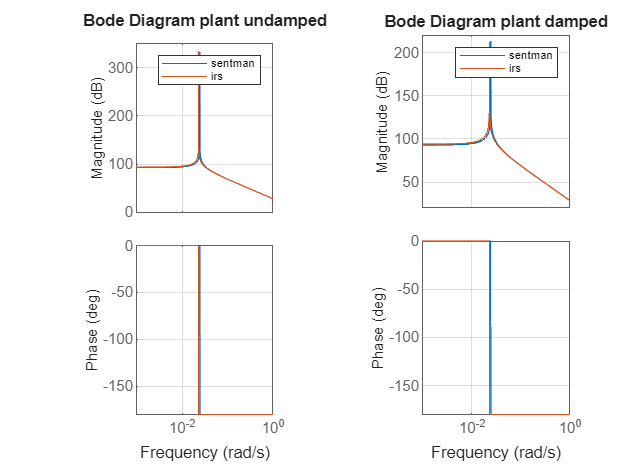

G_sentman = tf([1],[I_yy,0,-c_m_sentman]);
G_irs = tf([1],[I_yy,0,-c_m_irs]);
G_sentman_damped = tf([1],[I_yy,-c_q_sentman,-c_m_sentman]);
G_irs_damped = tf([1],[I_yy,-c_q_irs,-c_m_irs]);
figure;
subplot(1,2,1);
bodeplot(G_sentman,G_irs);
grid on;
title("Bode Diagram plant undamped")
legend("sentman","irs");
subplot(1,2,2);
bodeplot(G_sentman_damped,G_irs_damped)
grid on;
title("Bode Diagram plant damped")
legend("sentman","irs")

matlab2tikz('G_bode_pointing.tex','showInfo', false);

T_epsilon = 130;
zeta = 0.707;
omega_0 =-log(0.02*sqrt(1-zeta^2))/(zeta*T_epsilon)

omega_0 = 0.0463

omega_0_deg = rad2deg(omega_0)

omega_0_deg = 2.6547

k_p = I_yy * omega_0^2 + c_m_sentman

k_p = 5.7790e-05

k_d = 2* I_yy * zeta*omega_0

k_d = 0.0025


K = tf([k_d,k_p],1)


K =
 
  0.002457 s + 5.779e-05
 
Continuous-time transfer function.
Model Properties


G_0_sentman = K*G_sentman;
G_0_irs = K*G_irs;
T_sentman = feedback(G_0_sentman,1);%tf([k_d,k_p],[I_yy,k_d, (k_p-c_m_sentman)]);
T_irs = feedback(G_0_irs,1);%tf([k_d,k_p],[I_yy,k_d, (k_p-c_m_irs)]);

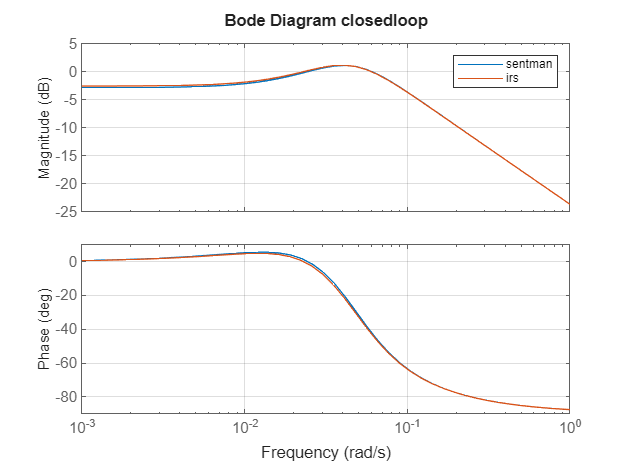

figure
bode(T_sentman,T_irs)
grid on;
title("Bode Diagram closedloop")
legend("sentman","irs")

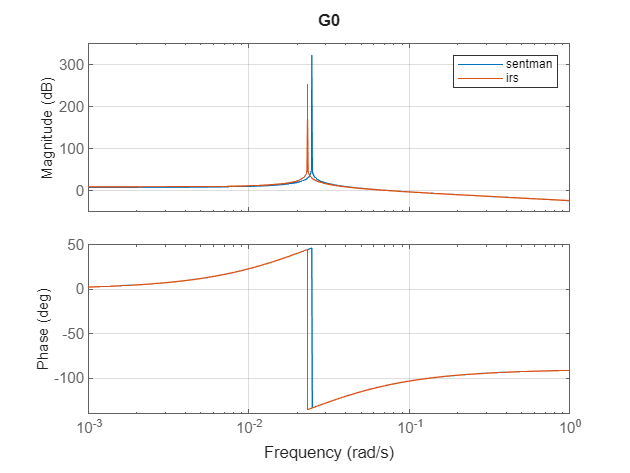

matlab2tikz('T_bode_pointing.tex','showInfo', false);
figure
bode(G_0_sentman,G_0_irs)
grid on;
title("G0")
legend("sentman","irs")

matlab2tikz('G0_bode_pointing.tex','showInfo', false);

offset = deg2rad(5)

offset = 0.0873

config = RespConfig(Bias=-offset,Amplitude = offset,Delay=0);
figure
hold on;
[y,tOut] = step(T_sentman,config);
y = rad2deg(y);
y = -(y./y(1)).*5;
plot(tOut,y,"b")
[y,tOut] = step(T_irs,config);
y = rad2deg(y);
y = -(y./y(1)).*5;
plot(tOut,y,"r")
yline(0,":")
ylabel("pitch angle [°]")
xlabel("Time [s]")
legend("sentman","irs")
matlab2tikz('stepresponse_pointing.tex','showInfo', false);

### Density influence

assumed constant $\alpha_e$ therefore forces and the stiffness scale linearly with density

particles_mass__kg = 16 * 1.6605390689252e-27;
n = 4.698e14;
nominal_density__kg_per_m3 = particles_mass__kg * n

nominal_density__kg_per_m3 = 1.2482e-11

n_min = 3.42e15

n_min = 3.4200e+15

n_max = 6.62e12

n_max = 6.6200e+12

density_max = particles_mass__kg*n_max

density_max = 1.7588e-13

density_min = particles_mass__kg*n_min

density_min = 9.0865e-11

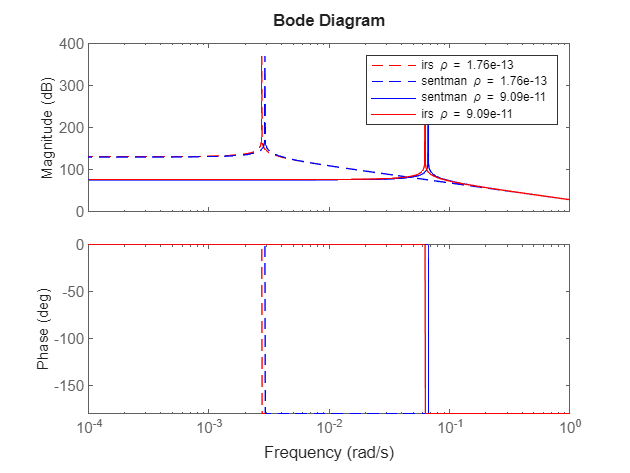


c_m_sentman_max = density_max/nominal_density__kg_per_m3 * c_m_sentman;
c_m_sentman_min = density_min/nominal_density__kg_per_m3 * c_m_sentman;
c_m_irs_max = density_max/nominal_density__kg_per_m3 * c_m_irs;
c_m_irs_min = density_min/nominal_density__kg_per_m3 *c_m_irs;

G_sentman_min = tf([1],[I_yy,0,-c_m_sentman_min]);
G_irs_min = tf([1],[I_yy,0,-c_m_irs_min]);
G_sentman_max = tf([1],[I_yy,0,-c_m_sentman_max]);
G_irs_max = tf([1],[I_yy,0,-c_m_irs_max]);

figure
bode(G_irs_max,"r--")
hold on;
bode(G_sentman_max,"b--")
bode(G_sentman_min,"b")
bode(G_irs_min,"r")
legend(sprintf("irs \\rho = %.2e",density_max),...
    sprintf("sentman \\rho = %.2e",density_max),...
    sprintf("sentman \\rho = %.2e",density_min),...
    sprintf("irs \\rho = %.2e",density_min))

matlab2tikz('G_bode_density_study.tex','showInfo', false);

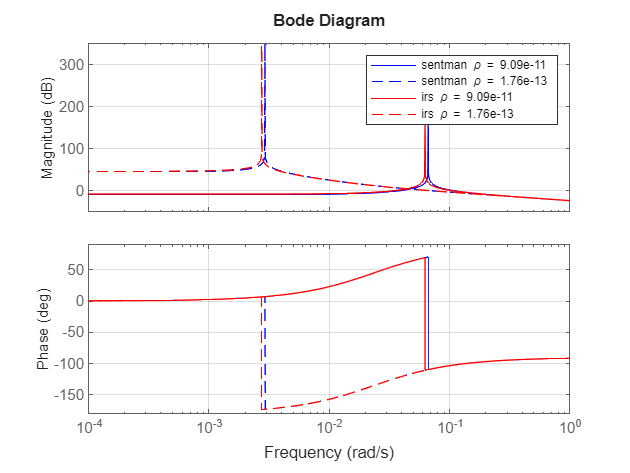

G_0_sentman_max = K*G_sentman_max;
G_0_sentman_min = K*G_sentman_min;
G_0_irs_max = K*G_irs_max;
G_0_irs_min = K*G_irs_min;

figure
hold on
bodeplot(G_0_sentman_min,"b");
bodeplot(G_0_sentman_max,"b--");
bodeplot(G_0_irs_min,"r");
bodeplot(G_0_irs_max,"r--");
grid on;

legend(sprintf("sentman \\rho = %.2e",density_min),...
    sprintf("sentman \\rho = %.2e",density_max),...
    sprintf("irs \\rho = %.2e",density_min),...
    sprintf("irs \\rho = %.2e",density_max))

matlab2tikz('G0_bode_density_study.tex','showInfo', false);
T_sentman_max = feedback(G_0_sentman_max,1);
T_irs_max = feedback(G_0_irs_max,1);
T_sentman_min = feedback(G_0_sentman_min,1);
T_irs_min = feedback(G_0_irs_min,1);

[G,P] = margin(G_0_sentman_max)

G = Inf

P = 71.2534

[G,P] = margin(G_0_sentman_min)

G = Inf

P = 77.7031

[G,P] = margin(G_0_irs_max)

G = Inf

P = 71.2502

[G,P] = margin(G_0_irs_min)

G = Inf

P = 77.3157

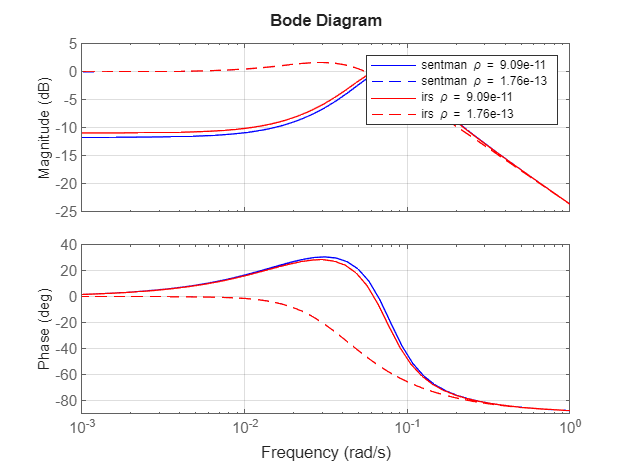

figure
hold on
bodeplot(T_sentman_min,"b");
bodeplot(T_sentman_max,"b--");
bodeplot(T_irs_min,"r");
bodeplot(T_irs_max,"r--");
grid on;
legend(sprintf("sentman \\rho = %.2e",density_min),...
    sprintf("sentman \\rho = %.2e",density_max),...
    sprintf("irs \\rho = %.2e",density_min),...
    sprintf("irs \\rho = %.2e",density_max))

matlab2tikz('T_bode_density_study.tex','showInfo', false);

offset = deg2rad(5)

offset = 0.0873

config = RespConfig(Bias=-offset,Amplitude = offset,Delay=0);
figure
hold on;
[y,tOut] = step(T_sentman_min,config);
y = rad2deg(y);
y = -(y./y(1)).*5;
plot(tOut,y,"b")
[y,tOut] = step(T_sentman_max,config);
y = rad2deg(y);
y = -(y./y(1)).*5;
plot(tOut,y,"b--")
[y,tOut] = step(T_irs_min,config);
y = rad2deg(y);
y = -(y./y(1)).*5;
plot(tOut,y,"r")
[y,tOut] = step(T_irs_max,config);
y = rad2deg(y);
y = -(y./y(1)).*5;
plot(tOut,y,"r--")
yline(0,":")
ylabel("pitch angle [rad]")
xlabel("Time [s]")
legend(sprintf("sentman \\rho = %.2e",density_min),...
    sprintf("sentman \\rho = %.2e",density_max),...
    sprintf("irs \\rho = %.2e",density_min),...
    sprintf("irs \\rho = %.2e",density_max));
matlab2tikz('stepresponse_density_study.tex','showInfo', false);

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.
